close all;
clear all;
clc;

N=512; % signal length
M=75; % select the number of DCT coefficients

%% Load the test signal
% Is load to array in mem on tellos mote B
load mit200
x= ecgsig(1:N, 1);

%% DCT transform of signal from telos B mote 
y = [-55.7299 -13.1481 11.4102 27.5574 0.2031 -54.8691 15.624 38.5892 -10.9977 -23.3673 19.4073 34.9809 -1.9823 -4.5880 -12.630 26.5077 4.1679 7.5850 -24.7809 23.5875 5.1476 16.6236 -18.2881 11.6090 4.3780 19.7274 -9.4010 0.1979 0.3907 15.266 6.9046 -5.2302 0.5558 1.4048 17.3511 -3.5341 1.8438 -10.4653 16.1673 0.8541 8.7889 -15.2104 9.6350 0.269 15.1313 -13.142 0.9512 -1.6313 12.8897 -1.2672 -3.7378 -5.1374 5.2191 5.9423 -1.6002 -3.5663 -2.3659 6.6895 0.4297 1.1252 -7.3969 3.6526 0.3098 4.1433 -8.655 0.1701 -3.374 5.374 -5.2628 -1.391 -5.6327 4.231 -2.7806 0.1299 -6.3781 1.2616 -1.6479 0.7899 -4.1330 -1.5373 -1.6692 0.1123 -2.202 -2.2143 -1.4233 -2.2167 0.7314 -2.4272 0.9612 -3.0 0.2459 -2.8273 1.8449 -3.4999 1.1528 -2.1270 1.4890 -1.8878 0.5662 -1.5193 1.6175 -1.4388 0.4685 -1.3657 0.5289 0.2336 0.1056 0.9943 0.882 1.5904 0.3121 0.8891 0.2593 0.8125 0.8937 1.3912 0.4096 0.9583 0.4636 1.7285 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 ];
% Scale the signal
y(1)=1/sqrt(N)*y(1);
y(2:end)=sqrt(2/N)*y(2:end);

%% reconstructed signal
x_rec=idct(y);

%% Mean squre error
mse(x,x_rec)

ans = 0.1190

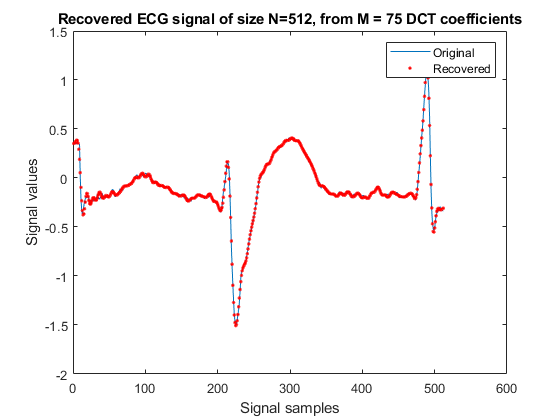

% Plot original
plot(x);

hold on;
% Plot restored
plot((x_rec) , 'r.' ) ;
title('Recovered ECG signal of size N=512, from M = 75 DCT coefficients');
xlabel('Signal samples'); 
ylabel('Signal values'); 
legend ('Original', 'Recovered');